clc
clear
%作者；暴富
%时间：2024-06-28
%项目：分蛋糕问题

%初始化状态
N = 25;
t = 1:N;
X = zeros(4,N);
X(1,1) = 2;
X(2,1) = 8;
X(3,1) = 4;
X(4,1) = 6;

%%迭代次数
% for k = 2:N
%     X(1,k) = (X(1,k-1)+X(2,k-1)+X(4,k-1))/3;
%     X(2,k) = (X(1,k-1)+X(2,k-1)+X(3,k-1))/3;
%     X(3,k) = (X(2,k-1)+X(3,k-1)+X(4,k-1))/3;
%     X(4,k) = (X(3,k-1)+X(4,k-1)+X(1,k-1))/3;
% end

for k = 2:N
    X(1,k) = X(1,k-1) + (X(2,k-1)-X(1,k-1)+X(4,k-1)-X(1,k-1))/3;
    X(2,k) = X(2,k-1) + (X(1,k-1)-X(2,k-1)+X(3,k-1)-X(2,k-1))/3;
    X(3,k) = X(3,k-1) + (X(2,k-1)-X(3,k-1)+X(4,k-1)-X(3,k-1))/3;
    X(4,k) = X(4,k-1) + (X(1,k-1)-X(4,k-1)+X(3,k-1)-X(4,k-1))/3;
end


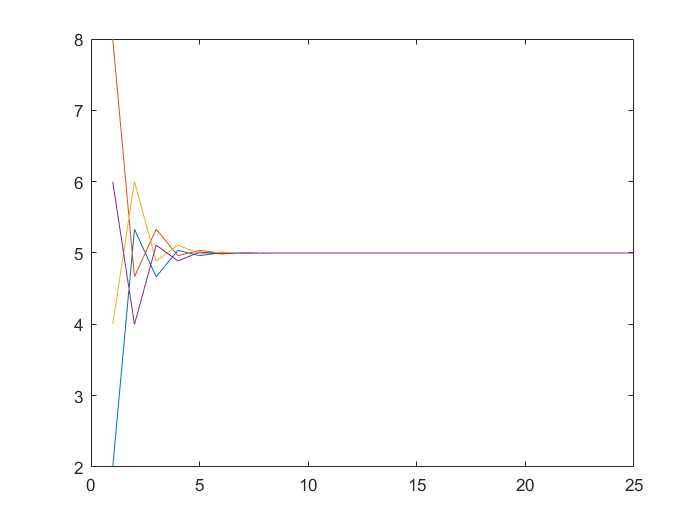

%%绘图
 
 
plot(t,X(1,:),t,X(2,:),t,X(3,:),t,X(4,:))